# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 20-Sep-2022 16:00:03

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([224 224 3],"Name","imageinput")
    convolution2dLayer([1 1],16,"Name","conv_1","Padding","same")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_1","Padding","same")
    reluLayer("Name","relu_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","conv_block1_Layer1","Padding","same")
    reluLayer("Name","relu_block1_RL1")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_block1_Layer2","Padding","same")
    reluLayer("Name","relu_block1_RL2")
    convolution2dLayer([1 1],16,"Name","conv_block1_Layer3","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","conv_block2_Layer1","Padding","same","Stride",[2 2])
    reluLayer("Name","relu_block2_RL1")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_block2_Layer2","Padding","same")
    reluLayer("Name","relu_block2_RL2")
    convolution2dLayer([1 1],32,"Name","conv_block2_Layer3","Padding","same")
    convolution2dLayer([1 1],32,"Name","conv_block3_Layer1","Padding","same")
    reluLayer("Name","relu_block3_RL1")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_block3_Layer2","Padding","same")
    reluLayer("Name","relu_block3_RL2")
    convolution2dLayer([1 1],32,"Name","conv_block3_Layer3","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","conv_block4_Layer1","Padding","same","Stride",[2 2])
    reluLayer("Name","relu_block4_RL1")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_block4_Layer2","Padding","same")
    reluLayer("Name","relu_block4_RL2")
    convolution2dLayer([1 1],32,"Name","conv_block4_Layer3","Padding","same")
    convolution2dLayer([1 1],32,"Name","conv_block5_Layer1","Padding","same")
    reluLayer("Name","relu_block5_RL1")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_block5_Layer2","Padding","same")
    reluLayer("Name","relu_block5_RL2")
    convolution2dLayer([1 1],32,"Name","conv_block5_Layer3","Padding","same")
    convolution2dLayer([1 1],48,"Name","conv_block6_Layer1","Padding","same","Stride",[2 2])
    reluLayer("Name","relu_block6_RL1")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_block6_Layer2","Padding","same")
    reluLayer("Name","relu_block6_RL2")
    convolution2dLayer([1 1],48,"Name","conv_block6_Layer3","Padding","same")
    convolution2dLayer([1 1],48,"Name","conv_block7_Layer1","Padding","same")
    reluLayer("Name","relu_block7_RL1")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_block7_Layer2","Padding","same")
    reluLayer("Name","relu_block7_RL2")
    convolution2dLayer([1 1],48,"Name","conv_block7_Layer3","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","conv_block8_Layer1","Padding","same")
    reluLayer("Name","relu_block8_RL1")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_block8_Layer2","Padding","same")
    reluLayer("Name","relu_block8_RL2")
    convolution2dLayer([1 1],48,"Name","conv_block8_Layer3","Padding","same")
    convolution2dLayer([1 1],96,"Name","conv_block9_Layer1","Padding","same","Stride",[2 2])
    reluLayer("Name","relu_block9_RL1")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_block9_Layer2","Padding","same")
    reluLayer("Name","relu_block9_RL2")
    convolution2dLayer([1 1],96,"Name","conv_block9_Layer3","Padding","same")
    convolution2dLayer([1 1],96,"Name","conv_block10_Layer1","Padding","same")
    reluLayer("Name","relu_block10_RL1")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_block10_Layer2","Padding","same")
    reluLayer("Name","relu_block10_RL2")
    convolution2dLayer([1 1],96,"Name","conv_block10_Layer3","Padding","same")
    convolution2dLayer([1 1],96,"Name","conv_block11_Layer1","Padding","same")
    reluLayer("Name","relu_block11_RL1")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_block11_Layer2","Padding","same")
    reluLayer("Name","relu_block11_RL2")
    convolution2dLayer([1 1],96,"Name","conv_block11_Layer3","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","conv_block12_Layer1","Padding","same","Stride",[2 2])
    reluLayer("Name","relu_block12_RL1")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_block12_Layer2","Padding","same")
    reluLayer("Name","relu_block12_RL2")
    convolution2dLayer([1 1],160,"Name","conv_block12_Layer3","Padding","same")
    convolution2dLayer([1 1],160,"Name","conv_block13_Layer1","Padding","same")
    reluLayer("Name","relu_block13_RL1")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_block13_Layer2","Padding","same")
    reluLayer("Name","relu_block13_RL2")
    convolution2dLayer([1 1],160,"Name","conv_block13_Layer3","Padding","same")
    convolution2dLayer([3 3],160,"Name","decoder_conv2d","Padding","same")
    reluLayer("Name","relu_2")
    transposedConv2dLayer([3 3],96,"Name","transposed-conv_1","Cropping","same","Stride",[2 2])
    reluLayer("Name","relu_3")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_2","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = crop2dLayer("centercrop","Name","crop2d_5");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(2,2,"Name","concat_1")
    convolution2dLayer([1 1],96,"Name","conv_2","Padding","same")
    reluLayer("Name","relu_4")
    transposedConv2dLayer([3 3],48,"Name","transposed-conv_2","Cropping","same","Stride",[2 2])
    reluLayer("Name","relu_5")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_3","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = crop2dLayer("centercrop","Name","crop2d_4");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(2,2,"Name","concat_2")
    convolution2dLayer([1 1],48,"Name","conv_3","Padding","same")
    reluLayer("Name","relu_6")
    transposedConv2dLayer([3 3],32,"Name","transposed-conv_3","Cropping","same","Stride",[2 2])
    reluLayer("Name","relu_7")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_4","Padding","same")
    convolution2dLayer([1 1],32,"Name","conv_4","Padding","same")
    reluLayer("Name","relu_8")
    transposedConv2dLayer([3 3],32,"Name","transposed-conv_4","Cropping","same","Stride",[2 2])
    reluLayer("Name","relu_9")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_5","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = crop2dLayer("centercrop","Name","crop2d_3");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(2,2,"Name","concat_3")
    convolution2dLayer([1 1],32,"Name","conv_5","Padding","same")
    reluLayer("Name","relu_10")
    transposedConv2dLayer([3 3],16,"Name","transposed-conv_5","Cropping","same","Stride",[2 2])
    reluLayer("Name","relu_11")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_6","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = crop2dLayer("centercrop","Name","crop2d_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(2,2,"Name","concat_4")
    convolution2dLayer([1 1],32,"Name","conv_6","Padding","same")
    reluLayer("Name","relu_12")
    transposedConv2dLayer([3 3],16,"Name","transposed-conv_6","Cropping","same")
    reluLayer("Name","relu_13")
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv_7","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = crop2dLayer("centercrop","Name","crop2d_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(2,2,"Name","concat_5")
    convolution2dLayer([1 1],32,"Name","conv_7","Padding","same")
    tanhLayer("Name","tanh")
    pixelClassificationLayer("Name","pixel-class")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"relu_1","conv_block1_Layer1");
lgraph = connectLayers(lgraph,"relu_1","crop2d_1/ref");
lgraph = connectLayers(lgraph,"conv_block1_Layer3","conv_block2_Layer1");
lgraph = connectLayers(lgraph,"conv_block1_Layer3","crop2d_2/ref");
lgraph = connectLayers(lgraph,"conv_block3_Layer3","conv_block4_Layer1");
lgraph = connectLayers(lgraph,"conv_block3_Layer3","crop2d_3/ref");
lgraph = connectLayers(lgraph,"conv_block7_Layer3","conv_block8_Layer1");
lgraph = connectLayers(lgraph,"conv_block7_Layer3","crop2d_4/ref");
lgraph = connectLayers(lgraph,"conv_block11_Layer3","conv_block12_Layer1");
lgraph = connectLayers(lgraph,"conv_block11_Layer3","crop2d_5/ref");
lgraph = connectLayers(lgraph,"groupedconv_2","crop2d_5/in");
lgraph = connectLayers(lgraph,"groupedconv_2","concat_1/in1");
lgraph = connectLayers(lgraph,"crop2d_5","concat_1/in2");
lgraph = connectLayers(lgraph,"groupedconv_3","crop2d_4/in");
lgraph = connectLayers(lgraph,"groupedconv_3","concat_2/in1");
lgraph = connectLayers(lgraph,"crop2d_4","concat_2/in2");
lgraph = connectLayers(lgraph,"groupedconv_5","crop2d_3/in");
lgraph = connectLayers(lgraph,"groupedconv_5","concat_3/in1");
lgraph = connectLayers(lgraph,"crop2d_3","concat_3/in2");
lgraph = connectLayers(lgraph,"groupedconv_6","crop2d_2/in");
lgraph = connectLayers(lgraph,"groupedconv_6","concat_4/in1");
lgraph = connectLayers(lgraph,"crop2d_2","concat_4/in2");
lgraph = connectLayers(lgraph,"groupedconv_7","crop2d_1/in");
lgraph = connectLayers(lgraph,"groupedconv_7","concat_5/in1");
lgraph = connectLayers(lgraph,"crop2d_1","concat_5/in2");

## Plot Layers

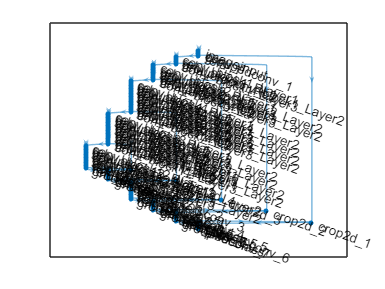

plot(lgraph);